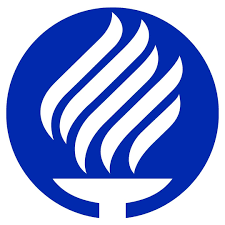

**Primer Entregable Reto**

**&**

**Segundo Entregable Reto**

Luis Andres Casillas A01645008

José Alfredo Vergara A0645391

Alí López Sarabia A01645060 

**Primer Entregable Reto**

En este primer entregable se busca modelar y visualizar el comportamiento de un bucle de corriente eléctrica que simula una bobina circular, así como calcular el campo magnético generado por dicha corriente. Además, se analiza el comportamiento de un imán al caer a través del campo magnético generado por el bucle, utilizando simulaciones basadas en la ley de Biot-Savart y las ecuaciones de movimiento.

**Marco Teórico**

**Corriente Eléctrica y Campos Magnéticos:**La corriente eléctrica se refiere al flujo de cargas eléctricas a través de un conductor. Según la ley de Biot-Savart, el campo magnético generado por un pequeño segmento de corriente es: 

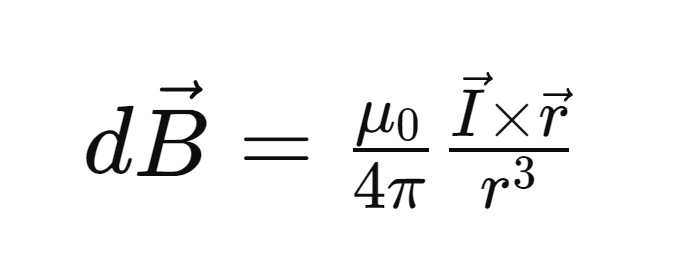

Un dipolo magnético en un campo magnético experimenta una fuerza y un torque que dependen del momento magnético y del campo magnético: 

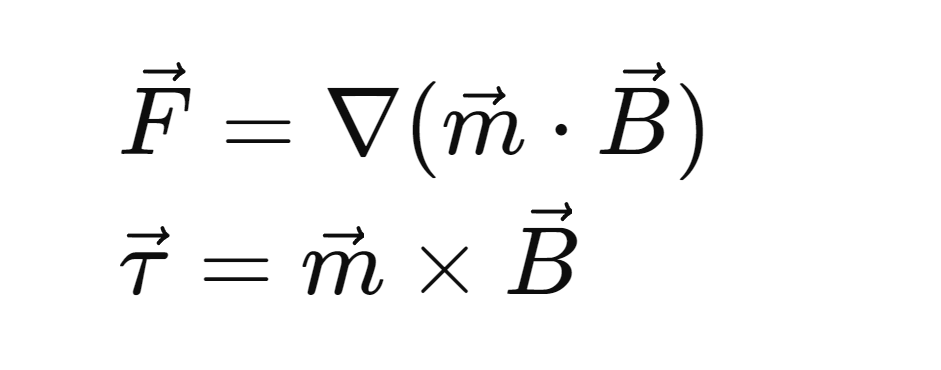

**Movimiento de un Imán:**El movimiento de un imán bajo la influencia de un campo magnético y la gravedad se puede modelar utilizando las ecuaciones de movimiento:

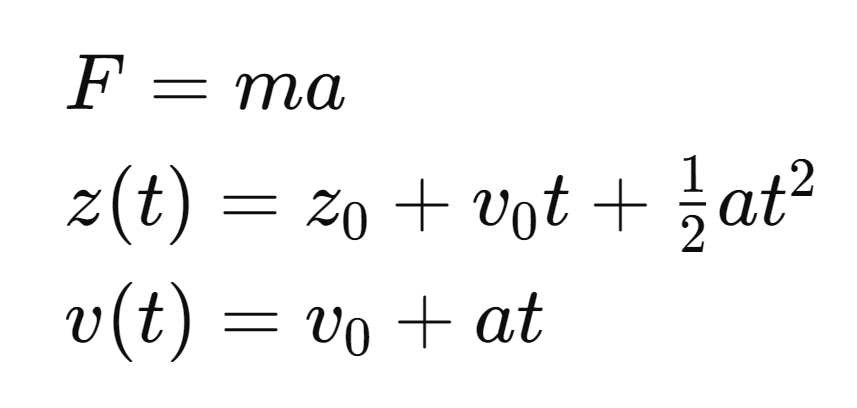

**Fórmulas Utilizadas**

- **Ley de Biot-Savart:**

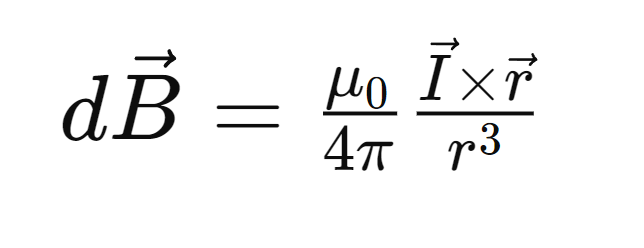

- Campo Magnético Total:

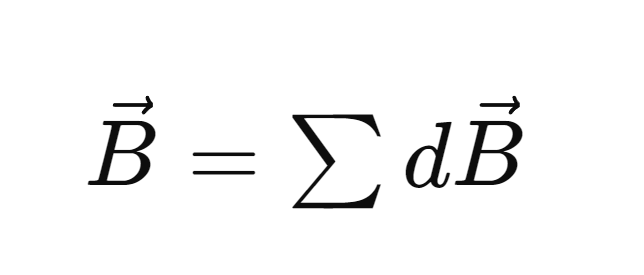

- Fuerza Magnética sobre el Imán:

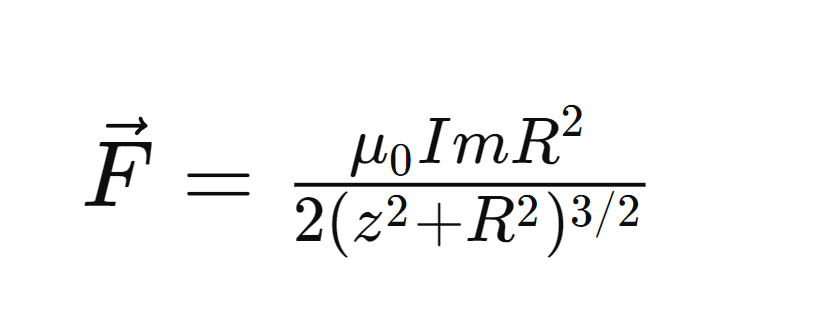

- Aceleración del Imán:

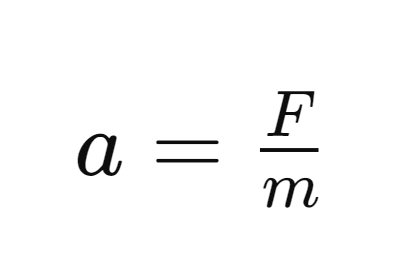

- Ecuaciones de Movimiento:

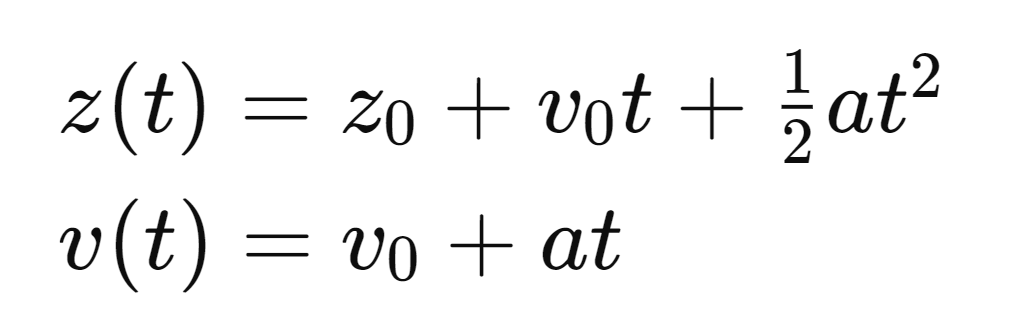

**Código Principal**

El código proporciona una simulación detallada que incluye la generación del campo magnético a través del bucle de corriente y la caída de un imán bajo la influencia de dicho campo. Utiliza MATLAB para realizar cálculos y visualizaciones.

Este entregable integra conceptos fundamentales de electromagnetismo y mecánica clásica para modelar y entender fenómenos físicos complejos de manera visual y computacional.

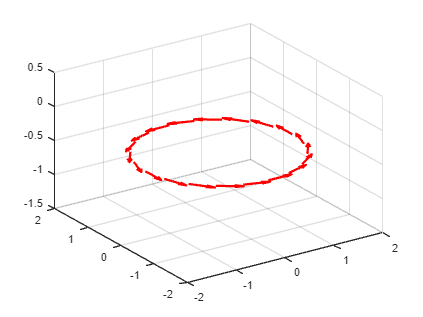

%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%   Sesión 1 | Paso 1
%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%Rodrigo Gamboa & Francisco Montes | Mayo 2024

%-OBJETIVO-%

%Crear y visualizar un bucle discretizado hecho de N flechas, 
%simbolizando diferenciales de corriente eléctrica, de modo que toda 
%la configuración se aproximará a un alambre circular (bobina), con una 
%corriente eléctrica constante asociada I. Cuantas más corrientes, mejor.

%Recordar comentar y completar todo el código necesario de ahora en adelante,
%ya que esto afectará la calidad y calificación del entregable asociado.

%-----------------------------------------------------------------------
%El código empieza aquí
%Completa el código a la izquierda, utilizando los comentarios a la derecha.
%-----------------------------------------------------------------------

clear all;          %Borrar todas las variables del espacio de trabajo
clc;          %Borrar la ventana de comandos
clf;           %Borrar todos los elementos en las figuras

nl = 1;               %Declarar una variable "nl" que representará el número de 
                      %bucles de alambre en tu simulación. Uno para una configuración llamada 
                      %una sola vuelta. Dos o más para una configuración 
                      %referida como múltiples vueltas. 



ds = 0.1;             %Declarar una variable "ds" para el diferencial de longitud.
                      %Establecerlo igual a 0.1 como punto de partida.


x = linspace(-5, 5); 
y = linspace(-5, 5);  
z=x;                       %Definir los vectores x, y, z, todos iguales, 
                                    %que van de -5 a 5, en pasos de ds.
                                    %Esto definirá nuestro espacio de trabajo 3D.
                                    
                                    %Cuando se haga correctamente, cada vector 
                                    %aparecerá en el espacio de trabajo como un 
                                    %array doble de 1x101.


Lx = length(x); 
Ly = length(y); 
Lz = length(z);                                 %Utilizando la función length(A), 
                                                %donde A puede ser un vector o array, 
                                                %declarar las variables Lx, Ly y Lz
                                                %estableciéndolas igual al número de elementos 
                                                %en los vectores x, y, z (es decir, la 
                                                %longitud de los vectores).



rw = 0.2;                                         %Utilizando una variable etiquetada rw, declarar el 
                                                %grosor del alambre, usar un valor de 0.2.


I = 300;                                           %Utilizando una variable I, declarar la 
                                                %corriente eléctrica asociada
                                                %(usar valor de 300 Amperios).


mo=4*pi*1e-7;                                   %¿Qué es esto? (¿Cuáles son las unidades? Henrios por metro (H/m) o teslas por amperio (T/A)).
km=mo*I/(4*pi);                                  %¿Y esto? (¿Cuáles son las unidades? Henrios (H)).
                        


N = 20;                      %Declarar una variable N, que definirá el número de puntos por bucle.
R = 1.5;                       %Declarar una variable R, como el radio del alambre, usar 1.5 como valor predeterminado.                  
sz = 1;                       %Declarar una variable sz, estableciéndola igual a 1. Esto representará el 
                            %tamaño del paso del bucle en la dirección del eje z.


s = 1;                          %Declarar una variable s (igual a 1), representando el "número" del bucle..

dtheta = (2*pi) / N;                          %Definir el "paso angular diferencial" (dtheta) con respecto al centro 
                            %del alambre circular (bobina), considerando que tiene que cubrir un
                            %desplazamiento angular de 2*pi. ¡Piénsalo!

dl = R * dtheta;                          %Definir el "diferencial de longitud" (dl), acoplado con el 
                            %dtheta asociado. Considerar que dtheta está en radianes.

                            
ang = 0:dtheta:(2*pi-dtheta);    %Definir un vector llamado "ang" (para ángulo), 
                                   %que va de 0 a 2*pi-dtheta, en pasos de dtheta.
                                   %Esto almacenará los valores angulares para completar un ciclo 
                                   %con pasos de dtheta, alrededor de la bobina. ¿Por qué de 
                                   %0 a 2*pi-dtheta? Para asegurar que el último valor angular sea exactamente 2π.


%Comenzar aquí un bucle for, iterando una variable ficticia
%que va de 1 a nl (el número de bucles en el sistema).


for i = 1:nl

%<dentro del bucle for>
%Descomentar las siguientes líneas, explorar y describir qué hace cada una de ellas

    Px(s:s+N-1)=R*cos(ang);           % Asigna las coordenadas x de los puntos en un círculo con radio R y ángulos ang.
    Py(s:s+N-1)=R*sin(ang);           % Asigna las coordenadas y de los puntos en el mismo círculo.
    Pz(s:s+N-1)=-nl/2*sz+(i-1)*sz;    % Asigna las coordenadas z de los puntos en el espacio, probablemente relacionadas con el eje z y el número de capas.

    dx(s:s+N-1)=-Py(s:s+N-1)*dtheta;  % Calcula la variación en las coordenadas x con respecto al ángulo.
    dy(s:s+N-1)=Px(s:s+N-1)*dtheta;   % Calcula la variación en las coordenadas y con respecto al ángulo.   

    s=s+N;                            % Actualiza el valor de s para avanzar a la siguiente sección de puntos en la iteración.
    
%End for loop here.  
end


dz(1:N*nl)=0;                         % Inicializa un vector dz con ceros.

%Llamar a la figura 1
figure(1)

%Usar la función quiver3, para visualizar el alambre de corrientes.
%Recordar que quiver3(X,Y,Z,U,V,W) grafica flechas con componentes direccionales
%U, V, y W en las coordenadas cartesianas especificadas por X, Y, y Z.

quiver3(Px,Py,Pz,dx,dy,dz,0.5,'-r','LineWidth',2)  %¿Para qué son las otras opciones? Escalado de flechas, color y ancho de línea.

%Descomentar para establecer una perspectiva de visualización adecuada.
view(-34,33) 

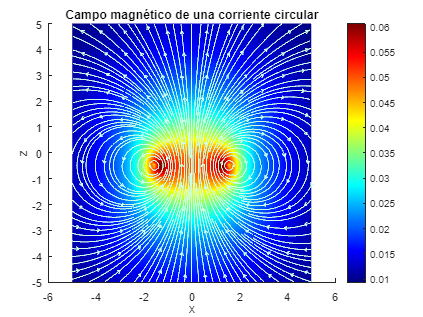


   



%%%%%%%%%%%%%%%%%%%%%%%%%%%
%   Sesión 1 | Paso 2    %
%%%%%%%%%%%%%%%%%%%%%%%%%%%
%Rodrigo Gamboa & Francisco Montes | Mayo 2024.

%Después de "Descomentar para establecer una perspectiva de visualización adecuada"
%view(-34,33) %del paso anterior.

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Cálculo y Visualización del Campo Magnético %
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%Utilizando los resultados obtenidos de la ley de Biot-Savart, obtener el campo B 
%en cada punto del espacio, alrededor del bucle de corriente.

dBx = zeros(Lx, Ly, Lz);
dBy = zeros(Lx, Ly, Lz);
dBz = zeros(Lx, Ly, Lz);          %Crear tres arrays iguales de 101x101x101, dBx, 
                                  %dBy y dBz, cada uno que abarca de 1
                                  %a Lx, de 1 a Ly y de 1 a Lz, e 
                                  %inicializar todos los valores a cero. Deberías
                                  %obtener en el espacio de trabajo tres objetos de 101x101x101
                                  %(dBx, dBy, dBz). 
                                  %¿Para qué crees que vamos a usar esto? Para almacenar los componentes del campo magnético.

for I = 1 : Lx;                   %Abrir un bucle for usando "I" como índice, que va de 1 a Lx.  
    for J = 1 : Ly;               %Lo mismo pero para Ly, usar un índice "J".
        for K = 1 : Lz;           %Lo mismo pero para Lz, usar un índice "K".   

            for L = 1 : nl*N      %Abrir un cuarto bucle for, usando un índice "L", que va de 1 a nl*N (¿Por qué? Para calcular la contribución de cada punto del bucle al campo magnético).

            %<dentro del cuarto bucle>
                                
            % Hacer un dibujo (diagrama), utilizando un vector de posición 
            % desde el centro de la bobina hasta cada elemento de corriente, dado por
            dr = Px(L) + Py(L) + Pz(L); %, y un vector de posición 
            % desde el centro de la bobina hasta el lugar en el espacio  
            % donde queremos calcular el campo B dado por 
            dR = x(I) + y(J) + z(K); %. Con esto, encontrar el vector de posición 
            % desde cada elemento de corriente hasta el lugar en el espacio  
            % donde queremos calcular el campo B, dado por   
            % r = (rx)i+(ry)j+(rz)k

            rx = x(I) - Px(L);     %Escribir aquí el componente rx
            ry = y(J) - Py(L);     %Lo mismo pero para el componente ry
            rz = z(K) - Pz(L);     %Lo mismo pero para el componente rz

            r = sqrt(rx^2 + ry^2 + rz^2 + rw^2);    %Obtener la magnitud

            r3 = r.^3;             %Declarar una variable r3 igual al tercer poder de r

            % Utilizando la expresión original de Biot-Savart, usar un 
            % dl = (dx)i+(dy)j y r = (rx)i+(ry)j+(rz)k para calcular el 
            % producto cruzado entre dl y r, para encontrar tres expresiones independientes
            % para los componentes del campo B que queremos
            % calcular, dBx(I,J,K), dBy(I,J,K) y dBz(I,J,K). No olvidar
            % actualizar o reescribir los componentes anteriores, entre cada
            % ciclo.
    
            dlx = -Py(L) * dtheta;  
            dly = Px(L) * dtheta;   

            dl = [dlx, dly, 0];  
            r_vec = [rx, ry, rz];   

            cross_product = cross(dl, r_vec);  

            dBx(I,J,K) = dBx(I,J,K) + km * (cross_product(1) / r3);  %Escribir aquí el componente dBx(I,J,K)
            dBy(I,J,K) = dBy(I,J,K) + km * (cross_product(2) / r3);  %Lo mismo pero para el componente dBy(I,J,K)
            dBz(I,J,K) = dBz(I,J,K) + km * (cross_product(3) / r3);  %Lo mismo pero para el componente dBz(I,J,K)
    
            %<dentro del cuarto bucle>

            end   %Cerrar el cuarto bucle

        end    %Cerrar el tercer bucle   
    end   %Cerrar el segundo bucle
end    %Cerrar el primer bucle

%------------------------------------------------------------
%Descomentar todo lo siguiente, y explicar (comentar) cada línea
%------------------------------------------------------------
clf;    

Bmag = sqrt(dBx.^2 + dBy.^2 + dBz.^2);    %Calcula la magnitud del campo magnético.

centery = round(Ly / 2);                %Encuentra el índice central de la dimensión y.
Bx_xz = squeeze(dBx(:, centery, :));    %Extrae el componente x del campo magnético en el plano xz.
Bz_xz = squeeze(dBz(:, centery, :));    %Extrae el componente z del campo magnético en el plano xz.
Bxz = squeeze(Bmag(:, centery, :));     %Extrae la magnitud del campo magnético en el plano xz.

figure(2)                           %Crea una nueva ventana de figura.
hold on

pcolor(x, z, (Bxz').^(1/3)); shading interp; colormap jet; colorbar    %Crea un gráfico de pseudocolor de la magnitud del campo magnético.
h1 = streamslice(x, z, Bx_xz', Bz_xz', 3);                                 %Crea líneas de flujo del campo magnético en el plano xz.
set(h1, 'Color', [0.8 1 0.9]);                                        %Establece el color de las líneas de flujo.
xlabel 'x'                                                           %Etiqueta el eje x.
ylabel 'z'                                                           %Etiqueta el eje z.
title 'Campo magnético de una corriente circular'                         %Establece el título del gráfico.
zz(length(ang)) = 0;   

%PASO 3

%Momento magnético del imán
mag = 2000;           %¿Cuáles son sus unidades? Amperios * metro^2

%Masa del imán en kg
mag_mass = 0.004;       %¿Cuántos gramos son esto? 4 gramos

%Peso del imán en N
w = mag_mass * -9.8;

zo = 5;                   %Declarar la posición inicial del imán usando una variable llamada "zo".

dt = 0.05;                %Paso de tiempo "dt"

zm(1) = zo;               %Declarar un vector llamado "zm" (posición del imán), y almacenar en su primer valor la variable de la posición inicial del imán.

%Posición del imán para el caso de caída libre. 
zmfree(1) = zo;          %¿Por qué crees que introdujimos esto? Para comparar la posición del imán con y sin efectos magnéticos.

tt(1) = 0;                %Declarar un vector llamado "tt" (tiempo), e inicializarlo a cero.

vz(1) = 0;                %Declarar un vector llamado "vz" (componente Z de velocidad), e inicializarlo a cero.

vzfree(1) = 0;            %Lo mismo que arriba pero ahora usando un vector etiquetado como "vzfree". Nuevamente, ¿por qué? Para rastrear la velocidad sin efectos magnéticos.

cc = 1;                   %Contador de índice

%Usar la función animatedline para crear una línea animada que no tenga datos y agregarla a los ejes actuales. Más adelante (unas líneas abajo), agregar puntos a la línea 
%en un bucle usando la función addpoints, agregar datos.

h = animatedline;

area = R * R * pi;
while zm(cc) > -5
 %Imprimir la posición del imán en z
    addpoints(animatedline, 0, zm(cc));
    drawnow
    head=scatter(0,zm(cc), 100,'filled');   %Descomentar esta línea y explicar lo que hace. Muestra la posición actual del imán como un círculo relleno.
    
    Fm(cc) = (6*mo*I*(R^2)*zm(cc)*mag)/(4*((zm(cc)^2+R^2)^(5/2)));    %Fuerza magnética Fm(cc)

    F(cc) = Fm(cc) + w;                                                  %Fuerza neta (total) sobre el imán F(cc), considerando Fm(cc) y su peso.      
                                                     
    a = F(cc)/mag_mass;       %Utilizando la fuerza total, obtener la aceleración instantánea y etiquetarla como "a".
    pause(0.01)        %Usar la función de pausa, con un valor de 0.01, para captar el movimiento del imán.

    zm(cc+1) = zm(cc) + vz(cc) *dt + 0.5*a*dt*dt;     %Obtener la nueva posición del imán zm(cc+1) utilizando física de la secundaria, es decir,
                      % utilizando ecuaciones de cinemática con aceleración constante. 

    zmfree(cc+1) = zmfree(cc)+vzfree(cc)*dt-0.5*9.81*dt*dt;     %Hacer lo mismo pero para el caso de caída libre, es decir, sin frenado magnético.
                      
    vz(cc+1) = (zm(cc+1)-zm(cc))/dt;   %Obtener la nueva velocidad del imán utilizando la definición básica de velocidad vz(cc+1) = delta(z)/delta(t)
                   

    vzfree(cc+1) = (zmfree(cc+1)-zmfree(cc))/dt;  %Hacer lo mismo pero para el caso de caída libre, es decir, sin frenado magnético.
                
    cc = cc + 1;                    %Aumentar el contador cc en una unidad.

   delete(head)     
                                

end    

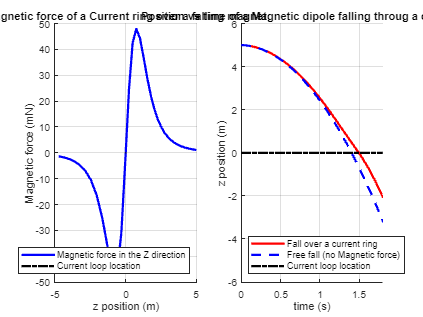



figure(4)
subplot(1,2,1)

hold on
plot(zm(1:length(Fm)),1000*Fm, '-b', 'LineWidth', 2) %¿Por qué tenemos 1000Fm? Para convertir la fuerza de newtons a milinewtons.
plot([0,0],[-.150,.150],'-.k','LineWidth', 2)
grid on
xlabel 'z position (m)'
ylabel 'Magnetic force (mN)'
title 'Magnetic force of a Current ring over a falling magnet'
legend('Magnetic force in the Z direction','Current loop location','Location','southeast')

subplot(1,2,2)

hold on
tt=0:dt:(cc-1)*dt;
plot(tt,zm,'-r', 'LineWidth', 2)
plot(tt,zmfree,'--b', 'LineWidth', 2)   
plot([0,1.8],[0,0],'-.k','LineWidth', 2)
grid on
xlabel 'time (s)'
ylabel 'z position (m)'
title 'Position vs time of a Magnetic dipole falling throug a current ring'
legend('Fall over a current ring','Free fall (no Magnetic force)', 'Current loop location','Location','southwest')
axis([0 1.8 -6 6])

(1) ¿Qué pasa si el momento magnético es cero? (ejecutar y explicar).

Si el momento magnético es cero, el imán no interactúa con el campo magnético.

Caerá libremente bajo la influencia de la gravedad, igual que en el caso de caída libre.

mag = 0;

(2) ¿Qué pasa si la masa del imán se establece en 1 kg? (ejecutar y explicar).

 Si la masa del imán se establece en 1 kg, la fuerza gravitacional será significativamente mayor,

 causando que el imán caiga más rápido. El efecto de frenado magnético será menos notable

 en comparación con un imán más ligero.

mag_mass = 1;

 Ejecutar la simulación con mag_mass = 1 para observar el efecto.

(3) ¿Qué pasa si aumentas el valor real del momento magnético en un orden de magnitud? (ejecutar y explicar).

 Aumentar el momento magnético en un orden de magnitud (por ejemplo, de 2000 a 20000 A*m^2)

 aumentará significativamente la fuerza magnética actuando sobre el imán. Esto resultará en 

 un efecto de frenado magnético más fuerte, haciendo que el imán caiga más lentamente.

mag = 20000;

 Ejecutar la simulación con mag = 20000 para observar el efecto.

(4) ¿Qué pasa si disminuyes la masa del imán en un orden de magnitud? (ejecutar y explicar).

 Disminuir la masa del imán en un orden de magnitud (por ejemplo, de 0.004 kg a 0.0004 kg)

 reducirá la fuerza gravitacional actuando sobre el imán. El efecto de frenado magnético será más

 pronunciado, haciendo que el imán caiga aún más lentamente.

mag_mass = 0.0004;

 Ejecutar la simulación con mag_mass = 0.0004 para observar el efecto.

(5) ¿Cuántos gráficos obtienes al final? Explica cada uno en detalle completo. ¡Detalles completos, por favor!

 Hay dos gráficos generados al final:

 Gráfico 1: Fuerza magnética de un anillo de corriente sobre un imán en caída

 Este gráfico muestra la fuerza magnética (en mN) como una función de la posición z del imán (en metros).

 La línea azul representa la fuerza magnética en la dirección z. La línea negra punteada indica

 la ubicación del anillo de corriente. Este gráfico ayuda a visualizar la variación en la fuerza magnética a medida que

 el imán cae a través del anillo de corriente.

 Gráfico 2: Posición vs tiempo de un dipolo magnético cayendo a través de un anillo de corriente

 Este gráfico muestra la posición z del imán (en metros) como una función del tiempo (en segundos).

 La línea roja representa la caída del imán sobre el anillo de corriente, considerando la fuerza magnética.

 La línea azul punteada representa la caída libre del imán, sin fuerza magnética.

 La línea negra punteada indica la ubicación del anillo de corriente. Este gráfico ayuda a visualizar la

 diferencia en la caída del imán con y sin el efecto de frenado magnético.

**------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------**

**------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------**

**Segundo Entregable Reto**

En el presente documento se detalla el desarrollo de un modelo para calcular el voltaje inducido (fuerza electromotriz o fem) generado por un imán en caída libre a lo largo del eje de un anillo conductor. El objetivo principal es simular la interacción entre el campo magnético del imán y el anillo, determinando cómo se induce la corriente eléctrica en el anillo debido a la variación del flujo magnético mientras el imán cae.

## Marco Teórico

Ley de Faraday de la Inducción Electromagnética

La Ley de Faraday establece que un cambio en el flujo magnético a través de un circuito induce una fuerza electromotriz (fem) en el circuito. Matemáticamente, se expresa como:

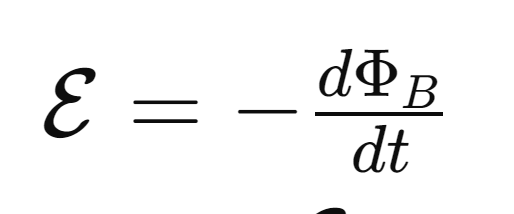

donde **ε** es la fem inducida y **Φ** es el flujo magnético.

**Flujo Magnético**

El flujo magnético a través de una superficie **S** se define como:

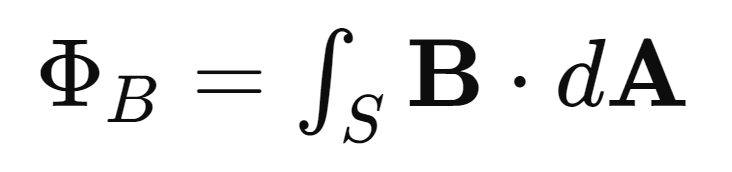

donde **B **es el campo magnético y** dA** es un elemento diferencial del área sobre la superficie **S**.

**Campo Magnético de un Dipolo Magnético**

El campo magnético producido por un dipolo magnético **m** en una posición** r** está dado por:

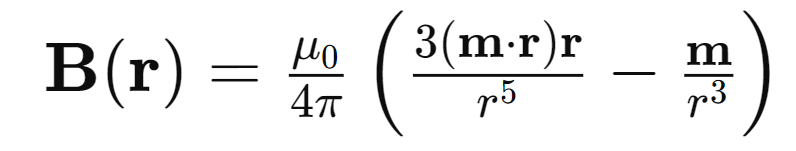

donde **μ0** es la permeabilidad del vacío, **m** es el momento dipolar magnético, y **r **es la distancia desde el dipolo al punto de interés.

## Desarrollo de las Fórmulas Utilizadas

Cálculo del Campo Magnético (**Bz**)

Para calcular el componente z del campo magnético (**Bz**) producido por un anillo de corriente eléctrica con radio **Rring** y momento magnético **mag**, se utiliza la expresión:

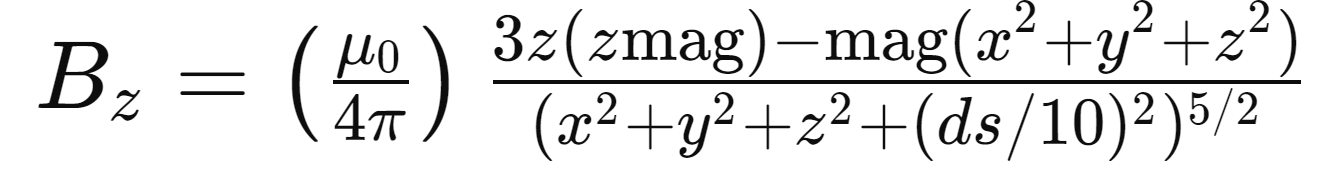

**Flujo Magnético (****Φ�****)**

El flujo magnético a través del anillo se obtiene sumando las contribuciones del campo magnético en cada punto de la malla:

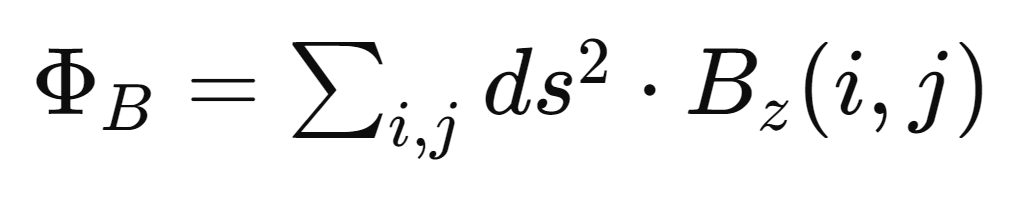

**Fuerza Electromotriz (fem)**

La fem inducida en el anillo se calcula como la derivada del flujo magnético respecto al tiempo:

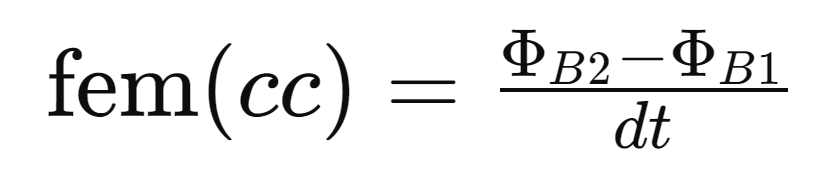

    donde **ΦB1** y **ΦB2** son los flujos magnéticos en dos instantes de tiempo consecutivos.

**Cinemática de la Caída Libre**

La posición (**zm**) y la velocidad (**vz**) del imán en caída libre se determinan mediante las ecuaciones de movimiento:

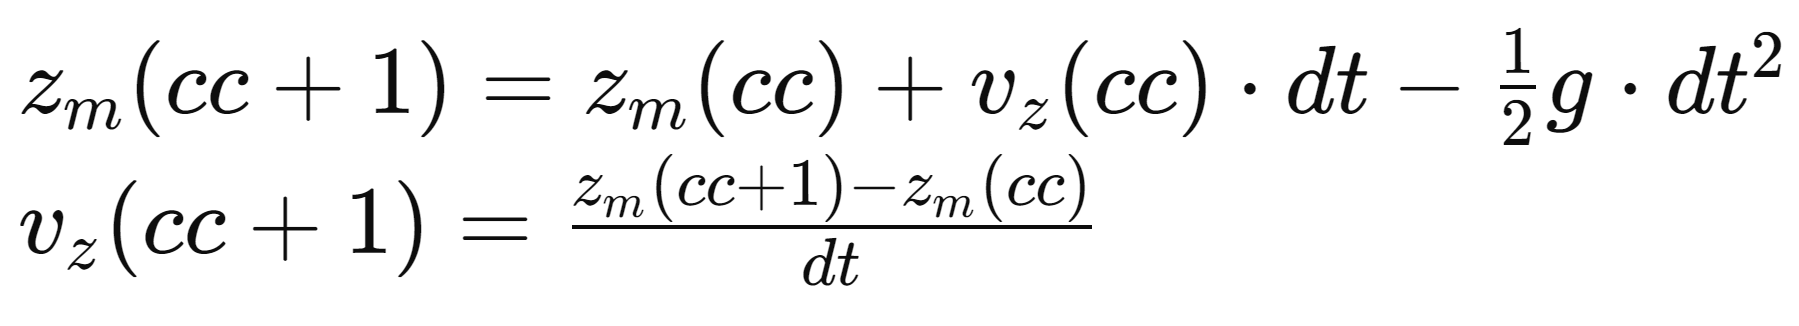

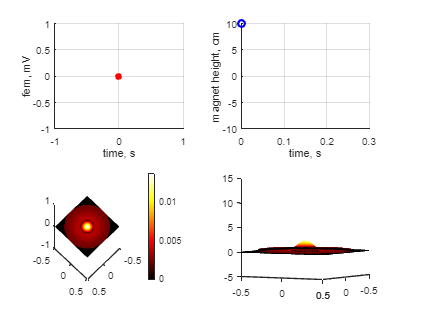

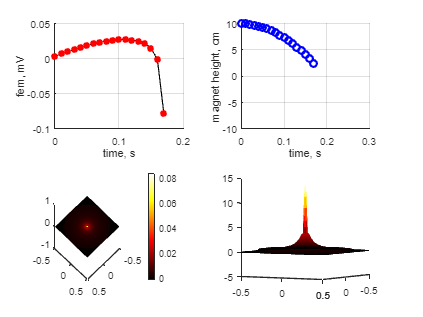

%-------------------------------%
%    Sesión de reto n.°4        %
%-------------------------------%
%Rodrigo Gamboa & Francisco Montes | May 2024


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%COMENTARIOS FINALES IMPORTANTES%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Este es tu SEGUNDO (y último) ENTREGABLE mínimo. El máximo (que te 
% garantizará una calificación directa de 100 en el entregable), y algo MUY 
% bien recibido para tu EXAMEN ORAL, es la integración de este código al 
% anterior (es decir, el del primer entregable). En pocas palabras, una 
% animación de un imán cayendo a través del eje de una bobina, experimentando 
% un frenado magnético debido a la corriente inducida por el imán que cae.


%%%%%%%%%%%%%%%%
%SESIÓN DE HOY %
%%%%%%%%%%%%%%%%

% El objetivo de esta sesión es modelar/encontrar el voltaje inducido 
% (diferencia de potencial o fuerza electromotriz, es decir fem), generado 
% por un imán en caída libre desde una altura zo, a lo largo del eje de un 
% anillo o loop conductor (con un radio Rring). IMPORTANTE: El conductor de 
% del loop ubicado en z=0 ya no tiene una corriente eléctrica constante, 
% como antes. La corriente asociada será generada por la fem inducida asociada.

% Supongamos que tenemos un imán con un momento dipolar magnético "mag". 
% Supongamos que el imán tiene un radio pequeño, 10 veces más pequeño que 
% el anillo. Modelemos el imán como un anillo de corriente eléctrica de 
% r=Rring/10. Calculemos el componente z del campo magnético producido por 
% ese anillo. 


%INICIA% PARTE I

clear             % Limpia todas las variables del espacio de trabajo
clc               % Limpia la ventana de comandos
clf               % Limpia todas las figuras abiertas

mag = 500;           % Define una variable "mag" para definir el momento magnético 
                     % del imán que cae y configúralo igual a 500.

Rring = 0.5;         % Define una variable "Rring" para definir el radio del anillo en m. Establece el valor 0.5.

zo = 0.1;            % Define la posición inicial del imán (zo). Dale un valor igual a 0.1
zring = 0;           % Define la posición del anillo (utilizar la variable "zring"). Dale un valor igual a 0.
dt = 0.01;           % Define el paso de tiempo ("dt"). Dale un valor igual a 0.01
t(1) = 0;            % Define un vector de tiempo (t) e inicializa en cero su primera entrada.

zm(1) = zo;          % Define un vector de posición Z (zm) e inicializa como "zo" su primera entrada.

cc = 1;              % Define un contador "cc"; configúralo igual a 1.
vz(1) = 0;           % Define un vector vz; inicializa su primera entrada a cero.

figure (1)           % Llama a la figure(1).

%--------Parte 2---------%
% Utiliza [abre y cierra] un loop while, usando el vector variable zm, de 
% modo que pueda garantizar que todos los valores z del imán mientras cae 
% desde zo hasta JUSTO ANTES de pasar por la bobina estén cubiertos 
% (es decir, desde zm = zo hasta zm = 0,0162).
while zm(cc)>=0.0162

    pause(0.001)     % Pausa la ejecución por 0.001 segundos
    clf              % Limpia la figura actual
    
    [x,y,phiB1,Bz]=B_due_M(zm(cc),mag,Rring);  

    % Esta función calcula el campo magnético Bz y el flujo magnético phiB
    % en las coordenadas (x, y) para un momento magnético "mag" y un radio "Rring" 
    % a una posición "zm". Se usa para obtener los valores iniciales antes de la actualización de la posición.

    % Usando cinemática, lo mismo que en el código de la semana pasada, escribe 
    % una expresión para la posición zm del imán, en caída libre.
    zm(cc+1) = zm(cc) + vz(cc) * dt - 0.5 * 9.81 * dt * dt;

    % Usando la cinemática, igual que en el código de la semana pasada, escribe 
    % una expresión para la velocidad vz del imán en caída libre.
    vz(cc+1) = (zm(cc+1) - zm(cc)) / dt;

    %--------Parte 4---------%
    % CÁLCULO DE LA fem | DECLARACIÓN
    
    %-- Después de la segunda llamada a la función
    [x,y,phiB2,Bz]=B_due_M(zm(cc+1),mag,Rring);
     
    % Teniendo en cuenta que la función B_due_M ha sido llamada dos veces 
    % (¿por qué?) Calcula una función vectorial de fem(cc) igual a la 
    % "velocidad de cambio o diferencia del flujo magnético, respecto del 
    % tiempo", asociada al área del anillo (bobina o espira de alambre).
    fem(cc) = (phiB2 - phiB1) / dt;

    % Descomenta todo lo siguiente y explica en detalle qué hace cada línea.
    figure(1) % Asegúrate de que la figura se mantenga activa
    subplot(2,2,1) % Divide la figura en una matriz de 2x2 y selecciona la primera subgráfica.
    hold on % Mantiene las gráficas existentes en la subgráfica actual para agregar más datos.
    grid on % Activa la cuadrícula en la subgráfica actual.
    xlabel 'time, s' % Añade una etiqueta al eje x con el texto 'time, s'.
    ylabel 'fem, mV' % Añade una etiqueta al eje y con el texto 'fem, mV'.
    plot(t(1:cc), 100 * fem(1:cc), '-k', 'LineWidth', 1) % Grafica la fem (fuerza electromotriz) en función del tiempo con una línea negra continua y grosor de línea de 1.
    plot(t(1:cc), 100 * fem(1:cc), '*r', 'LineWidth', 2) % Añade marcadores de estrella roja a la misma gráfica de fem en función del tiempo con un grosor de línea de 2.

    subplot(2,2,2) % Selecciona la segunda subgráfica en la matriz de 2x2.
    hold on % Mantiene las gráficas existentes en la subgráfica actual para agregar más datos.
    axis([0 0.3 -10 10]) % Establece los límites de los ejes x e y; x va de 0 a 0.3 y y va de -10 a 10.
    grid on % Activa la cuadrícula en la subgráfica actual.
    xlabel 'time, s' % Añade una etiqueta al eje x con el texto 'time, s'.
    ylabel 'magnet height, cm' % Añade una etiqueta al eje y con el texto 'magnet height, cm'.
    plot(t(1:cc), 100 * zm(1:cc), 'ob', 'LineWidth', 2) % Grafica la altura del imán en función del tiempo con marcadores de círculo azul y un grosor de línea de 2.

    subplot(2,2,3) % Selecciona la tercera subgráfica en la matriz de 2x2.
    hold on % Mantiene las gráficas existentes en la subgráfica actual para agregar más datos.
    pcolor(x, y, zm(cc) / abs(zm(cc)) * abs(abs(0.005^2 * Bz)).^(1/3)); % Crea una gráfica de color 2D de Bz escalado en función de x e y.
    shading interp; % Suaviza la interpolación de color entre los puntos.
    colormap hot; % Utiliza la paleta de colores 'hot' para la gráfica.
    colorbar % Añade una barra de color a la subgráfica para indicar la escala de valores.
    view(-45, -45) % Ajusta la vista de la gráfica a un ángulo de -45 grados en ambos ejes x e y.

    subplot(2,2,4) % Selecciona la cuarta subgráfica en la matriz de 2x2.
    hold on % Mantiene las gráficas existentes en la subgráfica actual para agregar más datos.
    mesh(x, y, zm(cc) / abs(zm(cc)) * abs(abs(10^2 * Bz)).^(1/3)); % Crea una gráfica de malla 3D de Bz escalado en función de x e y.
    view(-30, -3) % Ajusta la vista de la gráfica a un ángulo de -30 grados en x y -3 grados en y.
    axis([-Rring Rring -Rring Rring -5 15]) % Establece los límites de los ejes x, y, y z; x e y van de -Rring a Rring y z va de -5 a 15.

    cc = cc + 1; % Incrementa el contador 'cc' en 1.
    t(cc) = t(cc - 1) + dt; % Actualiza el tiempo para la siguiente iteración.
   
end

%¡¡¡ FIN DEL CÓDIGO !!!%

%------------Parte 3--------------% 
% DEFINICIÓN DE FUNCIÓN | DECLARACIÓN
%---------------------------------%

% Cambia el nombre de esta pestaña por el nombre de la función a la que se 
% hace referencia o está asociada (la que te trajo aquí en primer lugar). Por 
% ejemplo, si la función llamada en el código principal es f_meg(x,y), esta 
% pestaña debe llamarse f_meg.m para que Matlab la ubique. Asegúrate de 
% guardarla en el mismo directorio que tu código principal.

% Definición o declaración de una función llamada
% [x,y,phiB,Bz]=B_due_M(zm,mag,Rring);
% que toma (input) la posición "zm", el momento magnético "mag" y el radio "Rring"; y regresa (output)
% "x", "y", "phiB" y "Bz".

% Declara la función aquí, comienza por verificar la palabra/comando 
% reservado para MatLab, para declarar una función.


function [x,y,phiB,Bz]=B_due_M(zm,mag,Rring)
    mo = 4 * pi * 1e-7;     % Constante de permeabilidad magnética en el vacío
    ds = 0.005;             % Tamaño del paso para las matrices x e y

    x = -Rring:ds:Rring;    % Declara una matriz x, que se extiende desde -Rring a Rring en pasos de ds.   
    y = -Rring:ds:Rring;    % Declara una matriz y, que se extiende desde -Rring hasta Rring en pasos de ds.
    Lx = length(x);         % Define la longitud de la matriz x
    Ly = length(y);         % Define la longitud de la matriz y

    Bz = zeros(Lx, Ly);     % Define una matriz 2D, llamada Bz, con dimensiones Lx x Ly, e inicialízala en cero.
    phiB = 0;               % Introduce una variable llamada phiB y configúrala igual a cero.

    for i = 1:Lx            % Inicia un loop for utilizando un contador "i" que va de 1 a Lx.
        for j = 1:Ly        % Inicia un loop for utilizando un contador "j" que va de 1 a Ly

            r = sqrt(x(i)^2 + y(j)^2);  % Calcula la distancia radial desde el centro del anillo hasta el punto (x(i), y(j))

            if r < Rring  % Si la distancia radial es menor que el radio del anillo
                Bz(i,j) = (mo / (4 * pi)) * (3 * zm * (zm * mag) - mag * (x(i)^2 + y(j)^2 + zm^2)) / ((x(i)^2 + y(j)^2 + zm^2 + (ds / 10)^2)^(5 / 2));
                % Calcula el componente z del campo magnético Bz en el punto (x(i), y(j), zm)

                phiB = phiB + ds^2 * Bz(i,j);  % Calcula el flujo magnético phiB sumando los contribuciones de Bz en cada punto
            end
        end
    end
end

El proyecto desarrollado modela y simula el voltaje inducido (fem) generado por un imán en caída libre a través de un anillo conductor, basado en la Ley de Faraday de la Inducción Electromagnética. Utilizando MATLAB, se calcula el campo magnético producido por el imán y su variación temporal para determinar el flujo magnético y la fem inducida. La cinemática de la caída libre del imán se modela considerando tanto la gravedad como la fuerza magnética. Las visualizaciones generadas permiten analizar el comportamiento del voltaje inducido y la trayectoria del imán. La simulación muestra cómo factores como el momento magnético y la masa del imán afectan el voltaje inducido, ofreciendo una herramienta educativa y práctica para entender y diseñar sistemas electromagnéticos.